%% AVL design-space sweep / lookup-table builder
% Assumes run.cmd performs a full alpha sweep and extraction reads all values
% from polar_output.txt

clear
clc

% ---------------------------
% Paths
% ---------------------------

runDir  = 'C:\Users\OscarAntill\OneDrive - University of Bristol\group3\+Unconventional\+automation\runs';
avlPath = fullfile(runDir, 'avl352.exe');
outFile = fullfile(runDir, 'polar_output.txt');

assert(isfile(avlPath), 'avl352.exe not found')
assert(isfolder(runDir), 'runDir not found')
cd(runDir)

% ---------------------------
% Define baseline aircraft parameters
% ---------------------------

obj0 = struct();

% Reference geometry
obj0.WingArea = 800; % m^2 (will be overwritten)
obj0.CMAC = 5;       % placeholder
obj0.WingSpan = 50.0;

% Wing placement
obj0.WingStart = 30.0;
obj0.WingHeight = 0.0;
obj0.AOA_incident = 2.0;

% Wing geometry
obj0.RootChord = 15.0;
obj0.TipChord  = 4.5;
obj0.SweepAngle = 32;
obj0.DihedralAngle = 5;
obj0.Kinky = 0.30 * (obj0.WingSpan/2);

% Control surfaces
obj0.FlapStart    = 0.75;
obj0.AileronStart = 0.75;

% ---------------------------
% Horizontal tail
% ---------------------------

obj0.HStabStart = 60.0;

obj0.HRootChord = 6.0;
obj0.HTipChord  = 1.5;

obj0.TailSpan = 25.0;
obj0.HalfTailSpan = obj0.TailSpan/2;

obj0.HSweepAngle = 40;
obj0.HDihedralAngle = 2;

obj0.ElevatorHinge = 0.7;

% ---------------------------
% Vertical tail
% ---------------------------

obj0.VStabStart = 61;

obj0.VRootChord = 5.0;
obj0.VTipChord  = 1.8;

obj0.VSweepAngle = 40;
obj0.VTailSpan = 16.0;

obj0.RudderHinge = 0.7;

% ---------------------------
% Airfoils
% ---------------------------

obj0.HorAerofoil = 'naca0012.dat';
obj0.VerAerofoil = 'naca0012.dat';
WingAirfoil = 'SC(2)-0610.dat';

% ---------------------------
% Additional Aircraft Parameters
% ---------------------------

obj0.tc       = 0.12;
obj0.tc_ht    = 0.10;
obj0.tc_vt    = 0.10;

obj0.CLmax_clean = 1.5;
obj0.CLmax_flap  = 2.6;

obj0.FuselageLength   = 75;
obj0.FuselageDiameter = 7.0;

obj0.N_eng = 2;
obj0.NacelleLength   = 8.0;
obj0.NacelleDiameter = 3.5;

obj0.MTOM    = 490000;
obj0.Payload = 85000;
obj0.OEW     = 250000;

obj0.CruiseMach = 0.78;
obj0.CruiseAlt  = 11000;

obj0.g = 9.81;

% ---------------------------
% Design space
% ---------------------------

spanVec       = linspace(68, 78, 5);    % m
dihedralVec   = 5;                      % deg
kinkFracVec   = 0.30;                   % fraction of semispan
rootChordVec  = linspace(13, 17, 4);    % m
taperRatioCommon = 0.30;

machVec       = linspace(0.78, 0.85, 7);  % Mach
altVec        = linspace(8000, 11000, 12); % m

% This must match what run.cmd is sweeping
alphaVec = -2:1:10;

% ---------------------------
% Preallocate results
% ---------------------------

nGeom = numel(spanVec) * numel(dihedralVec) * ...
        numel(kinkFracVec) * numel(rootChordVec);

nCond = numel(machVec) * numel(altVec);
nAlpha = numel(alphaVec);
nRows  = nGeom * nCond * nAlpha;

Results(nRows,1) = struct( ...
    'CaseID', [], ...
    'SweepAngle', [], ...
    'WingSpan', [], ...
    'DihedralAngle', [], ...
    'KinkLocation', [], ...
    'RootChord', [], ...
    'TipChord', [], ...
    'TaperRatio', [], ...
    'WingArea', [], ...
    'AspectRatio', [], ...
    'Mach', [], ...
    'Altitude', [], ...
    'Alpha', [], ...
    'CL', [], ...
    'CD', [], ...
    'CD0', [], ...
    'Status', [] );

row = 0;
caseID = 0;
i = 0;

% ---------------------------
% Main design-space loop
% ---------------------------

for iSpan = 1:numel(spanVec)
    for iDih = 1:numel(dihedralVec)
        for iKink = 1:numel(kinkFracVec)
            for iRoot = 1:numel(rootChordVec)

                obj = obj0;

                % Independent geometry variables
                obj.WingSpan      = spanVec(iSpan);
                obj.DihedralAngle = dihedralVec(iDih);
                obj.RootChord     = rootChordVec(iRoot);
                obj.TipChord      = taperRatioCommon * obj.RootChord;
                obj.SweepAngle    = Unconventional.aerodynamics.wingsweep(obj.CruiseMach);

                % Geometry sanity checks
                if obj.TipChord <= 0 || obj.RootChord <= 0
                    continue
                end

                if obj.TipChord >= obj.RootChord
                    continue
                end

                obj.Kinky = kinkFracVec(iKink) * (obj.WingSpan/2);

                % Wing geometry - X/Z offsets
                [Tipx,Tipz] = Unconventional.automation.leading_offset( ...
                    obj.SweepAngle, obj.DihedralAngle, obj.WingSpan/2);

                [Kinkx,Kinkz] = Unconventional.automation.leading_offset( ...
                    obj.SweepAngle, obj.DihedralAngle, obj.Kinky);

                obj.Tipx = Tipx;
                obj.Tipz = Tipz;

                obj.Kinkx = Kinkx;
                obj.Kinkz = Kinkz;
                obj.KinkChord = obj.RootChord - Kinkx;

                if obj.KinkChord <= 0
                    continue
                end

                % Tail offsets
                [HTailx,HTailz] = Unconventional.automation.leading_offset( ...
                    obj.HSweepAngle, obj.HDihedralAngle, obj.TailSpan/2);
                obj.HTipx = HTailx;
                obj.HTipz = HTailz;

                [VTailx,~] = Unconventional.automation.leading_offset( ...
                    obj.VSweepAngle, 0.0, obj.TailSpan/2);
                obj.VTipX = VTailx;

                % Derived planform quantities
                semiSpan = obj.WingSpan / 2;
                y1 = obj.Kinky;
                y2 = semiSpan - y1;

                S_semi = 0.5 * (obj.RootChord + obj.KinkChord) * y1 + ...
                         0.5 * (obj.KinkChord + obj.TipChord)  * y2;

                obj.WingArea = 2 * S_semi;
                obj.AR = obj.WingSpan^2 / obj.WingArea;
                obj.WingLoading = (obj.MTOM * obj.g) / obj.WingArea;

                taperRatio = obj.TipChord / obj.RootChord;

                obj.CMAC = (2/3) * obj.RootChord * ...
                           ((1 + taperRatio + taperRatio^2) / (1 + taperRatio));

                for iMach = 1:numel(machVec)
                    for iAlt = 1:numel(altVec)

                        caseID = caseID + 1;

                        Mach = machVec(iMach);
                        Alt  = altVec(iAlt);

                        obj.CruiseMach = Mach;
                        obj.CruiseAlt  = Alt;
                        obj.SweepAngle = Unconventional.aerodynamics.wingsweep(Mach);

                        % Rebuild wing geometry if sweep changes with Mach
                        [Tipx,Tipz] = Unconventional.automation.leading_offset( ...
                            obj.SweepAngle, obj.DihedralAngle, obj.WingSpan/2);

                        [Kinkx,Kinkz] = Unconventional.automation.leading_offset( ...
                            obj.SweepAngle, obj.DihedralAngle, obj.Kinky);

                        obj.Tipx = Tipx;
                        obj.Tipz = Tipz;

                        obj.Kinkx = Kinkx;
                        obj.Kinkz = Kinkz;
                        obj.KinkChord = obj.RootChord - Kinkx;

                        if obj.KinkChord <= 0
                            continue
                        end

                        semiSpan = obj.WingSpan / 2;
                        y1 = obj.Kinky;
                        y2 = semiSpan - y1;

                        S_semi = 0.5 * (obj.RootChord + obj.KinkChord) * y1 + ...
                                 0.5 * (obj.KinkChord + obj.TipChord)  * y2;

                        obj.WingArea = 2 * S_semi;
                        obj.AR = obj.WingSpan^2 / obj.WingArea;
                        obj.WingLoading = (obj.MTOM * obj.g) / obj.WingArea;

                        taperRatio = obj.TipChord / obj.RootChord;

                        obj.CMAC = (2/3) * obj.RootChord * ...
                                   ((1 + taperRatio + taperRatio^2) / (1 + taperRatio));

                        % ---------------------------
                        % Build AVL geometry
                        % ---------------------------

                        Unconventional.automation.construct_avl(obj, Mach, Alt, WingAirfoil);

                        % ---------------------------
                        % Run AVL
                        % ---------------------------
                        % Assumes run.cmd already exists and looks like:
                        % LOAD unconventional.avl
                        % OPER
                        % A -6 X ... A 10 X
                        % QUIT

                        if isfile(outFile)
                            delete(outFile)
                        end

                        [status, cmdout] = system(['"' avlPath '" < run.cmd > polar_output.txt']); %#ok<NASGU>

                        fprintf('Case %d complete. status = %d\n', caseID, status);

                        if ~isfile(outFile)
                            warning('polar_output.txt missing for case %d', caseID);
                            continue
                        end

                        % ---------------------------
                        % Read AVL output
                        % ---------------------------

                        txt = fileread(outFile);

                        alphaTok = regexp(txt,'Alpha\s*=\s*([-+]?\d*\.?\d+)','tokens');
                        alphaRun = cellfun(@(x) str2double(x{1}), alphaTok);

                        CLtok = regexp(txt,'CLtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
                        CLrun = cellfun(@(x) str2double(x{1}), CLtok);

                        CDtok = regexp(txt,'CDtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
                        CDrun = cellfun(@(x) str2double(x{1}), CDtok);

                        n = min([length(alphaRun), length(CLrun), length(CDrun)]);

                        if n == 0
                            warning('No valid AVL data extracted for case %d', caseID);
                            continue
                        end

                        alphaRun = alphaRun(1:n);
                        CLrun    = CLrun(1:n);
                        CDrun    = CDrun(1:n);

                        [alphaRun, uniqueIdx] = unique(alphaRun, 'stable');
                        CLrun = CLrun(uniqueIdx);
                        CDrun = CDrun(uniqueIdx);

                        % ---------------------------
                        % Compute drag build-up
                        % ---------------------------

                        try
                            CD0_here = Unconventional.aerodynamics.testdragbuildup(obj, Alt, Mach);
                        catch
                            CD0_here = NaN;
                        end

                        % ---------------------------
                        % Store results
                        % ---------------------------
                        i = i + 1;
                        for ia = 1:numel(alphaRun)
                            row = row + 1;

                            Results(row).CaseID         = caseID;
                            Results(row).SweepAngle     = obj.SweepAngle;
                            Results(row).WingSpan       = obj.WingSpan;
                            Results(row).DihedralAngle  = obj.DihedralAngle;
                            Results(row).KinkLocation   = obj.Kinky;
                            Results(row).RootChord      = obj.RootChord;
                            Results(row).TipChord       = obj.TipChord;
                            Results(row).TaperRatio     = taperRatio;
                            Results(row).WingArea       = obj.WingArea;
                            Results(row).AspectRatio    = obj.AR;
                            Results(row).Mach           = Mach;
                            Results(row).Altitude       = Alt;
                            Results(row).Alpha          = alphaRun(ia);
                            Results(row).CL             = CLrun(ia);
                            Results(row).CD             = CDrun(ia);
                            Results(row).CD0            = CD0_here;
                            Results(row).Status         = status;
                        end

                        % checkpoint save
                        validRows = ~arrayfun(@isempty, {Results.CaseID});
                        ResultsValid = Results(validRows);

                        save(fullfile(runDir, 'AVL_lookup_checkpoint.mat'), ...
                             'ResultsValid', ...
                             'spanVec', 'dihedralVec', ...
                             'kinkFracVec', 'rootChordVec', ...
                             'alphaVec', 'machVec', 'altVec', 'taperRatioCommon');
                    end
                end
            end
        end
    end
end

% ---------------------------
% Trim unused rows and save
% ---------------------------

validRows = ~arrayfun(@isempty, {Results.CaseID});
Results = Results(validRows);

save(fullfile(runDir, 'AVL_lookup_table.mat'), ...
     'Results', ...
     'spanVec', 'dihedralVec', ...
     'kinkFracVec', 'rootChordVec', ...
     'alphaVec', 'machVec', 'altVec', 'taperRatioCommon');

disp('Lookup table saved: AVL_lookup_table.mat')


## ---------------------------

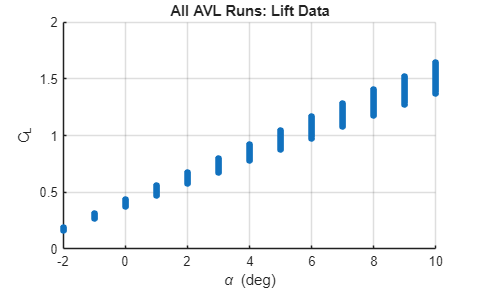


% Example plots
% ---------------------------

allAlpha = [Results.Alpha]';
allCL    = [Results.CL]';
allCD    = [Results.CD]';

figure
scatter(allAlpha, allCL, 25, 'filled')
xlabel('\alpha (deg)')
ylabel('C_L')
grid on
title('All AVL Runs: Lift Data')

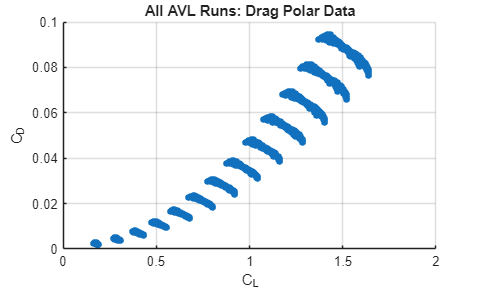


figure
scatter(allCL, allCD, 25, 'filled')
xlabel('C_L')
ylabel('C_D')
grid on
title('All AVL Runs: Drag Polar Data')